システム同定?

seri = serialport("COM9", 57600, "ByteOrder", "big-endian", "Timeout", 0.1);

SAMPLING_TIME = 0.025;  % 1サンプルの頻度は25[ms]程度であることを予備実験で確認
INPUT_VOLTAGE = 0;
STEP_TIME = 2;
END_TIME = 10;

Kp = 10/200000;
%Kp = 20;

%初期値取得
for i = 1 : 100
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pc(i) = sci_read_with_decode_using_checksum(seri);
end

% BASE = 0x30d40; %20万
% BASE = 0x3FFFF
% GOAL_ANGLE = 30/360 * BASE;

BASE = double(0x3FFFF); %262143。18bit全て1
GOAL_ANGLE = pi/6;

pause(10);
for i = 1 : (END_TIME / SAMPLING_TIME)
    tic;
    if (i >= STEP_TIME / SAMPLING_TIME)
        
        %INPUT_VOLTAGE = double(Kp*(GOAL_ANGLE - uint32(sh2pc2(i-1).BaseAngle)));
        INPUT_VOLTAGE = Kp*(GOAL_ANGLE - 2*pi*double(sh2pc2(i-1).BaseAngle)/BASE);
        disp("INPUT=");
        disp(INPUT_VOLTAGE);
        
        if abs(INPUT_VOLTAGE) > 1
            INPUT_VOLTAGE = double(sign(INPUT_VOLTAGE));
        end
        
        write(seri, typecast(swapbytes(INPUT_VOLTAGE), 'uint8'), 'uint8');
    else
        write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    end
    
    sh2pc2(i) = sci_read_with_decode_using_checksum(seri);
    
    volts(i)=INPUT_VOLTAGE;
    angles(i)=double(sh2pc2(i).BaseAngle)/BASE;
    
    disp(i);
    disp(INPUT_VOLTAGE);
    disp(double(sh2pc2(i).BaseAngle)/BASE)
    pause(SAMPLING_TIME - toc);
end

clear sh2pc2 volts angles

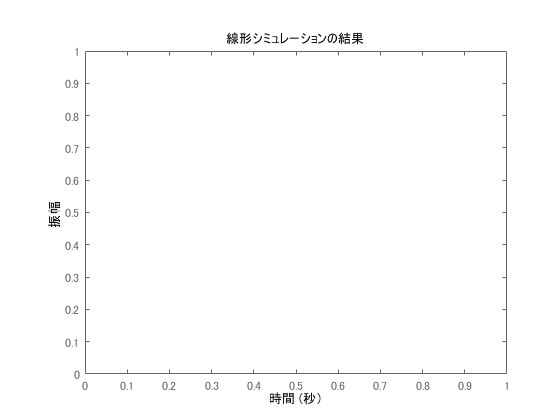

write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');

pause(0.5);
clear s;
clear sh2pc;

ans =          0
    0.0006
    0.0025
    0.0055
    0.0095
    0.0144
    0.0201
    0.0265
    0.0336
    0.0412


plot(angles*2*pi);
plot(angles*360);

%モータの出力プロット
sh2pc2table=struct2table(sh2pc2);
t = sh2pc2table.TMStamp - sh2pc2table.TMStamp(1);
y = double(sh2pc2table.BaseAngle)*360/BASE;
plot(t/1000, y);

%%ArmAngleの特性を見る
pause(15);
for i = 1 : 2000
    disp(i);
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pc3(i) = sci_read_with_decode_using_checksum(seri);
end

sh2pc3Table=struct2table(sh2pc3);
plot(sh2pc3Table.ArmAngle);

## ピークの抽出

%locs=ピークのインデックス
[pks,locs] = findpeaks(double(sh2pc3Table.ArmAngle));
%arm_peaks=sh2pc3Table.ArmAngle(locs(locs >= 289));
peak_idxs = [563 648 689];
arm_rate_sum = 0;


arm_rate_sum = arm_rate_sum + double(sh2pc3Table.ArmAngle(peak_idxs(2)))/double(sh2pc3Table.ArmAngle(peak_idxs(1)));
arm_rate_sum = arm_rate_sum + double(sh2pc3Table.ArmAngle(peak_idxs(3)))/double(sh2pc3Table.ArmAngle(peak_idxs(2)));

arm_rate =  arm_rate_sum / 2;


%%振動周期
arm_period_sum = 0;
arm_peaks_times=sh2pc3Table.TMStamp(peak_idxs);


for k = 1 : 2
    
    arm_period_sum = arm_period_sum + (arm_peaks_times(k+1)-arm_peaks_times(k));
    
end

arm_period = arm_period_sum / 2;

%%ステップ数で振動周期
peak_steps = locs(locs >= 289);
peak_steps_sum = 0;

for k = 1 : (length(peak_steps)-1)
    
    peak_steps_sum = peak_steps_sum + (peak_steps(k+1)-peak_steps(k));
    
end

peak_steps_mean = peak_steps_sum / 32;

t = sh2pc3Table.TMStamp - sh2pc3Table.TMStamp(1);
y = sh2pc3Table.ArmAngle;
plot(t, y);

pause(5);
for i = 1 : 1000
    disp(i);
    write(seri, typecast(swapbytes(0), 'uint8'), 'uint8');
    sh2pc4(i) = sci_read_with_decode_using_checksum(seri);
end

lsim(tf(b*20, [1 a k*20]))

t_sim = 0:0.01:9;
theta1_sim = (pi/6)*step(q_wn2, [1 a q_wn2], t_sim);
hold on
plot(t_sim, theta1_sim*180/pi)